# Robot Arm Visualization

## Task 1

The robot arm has four parameters. It has lengths `L1` and `L2` for the two links, and angles of rotation `theta1` and `theta2` for the two joints.

Task

Create symbolic variables for the four parameters of the robot arm: `L1`, `L2`, `theta1`, and `theta2`.

syms L1 L2 theta1 theta2
syms

Your symbolic variables are:

A        AE       AVec     E        KE       L1       L2       PE       a        aInt     aPos     aSol     asol     b        bInt     bPos     bSol     bsol     c        check    consE    const    d        e        eqn      eqn2     eqn3     eqnAdd   eqnMult  ex       ex2      expr     f        g        h        m        pyth     quadeqn  quadsol  r        realsol  s        sol      t        theta1   theta2   un       v        vSI      val      vkph     w        x        xsol     xsol2    xsym     y        yCubic   yLinear  yexp     yfact    ymult    ys       ysimp    ysym     z                                                                                                                                                                                                                                                                                                                                                                                                

## Task 2

The x and y

 coordinates of the end effector can be found using the following formulas:

x=L2cos(*θ*1+*θ*2)+L1cos(*θ*1)

y=L2sin(*θ*1+*θ*2)+L1sin(*θ*1)

Task

Store the expressions for the x and y coordinates of the end effector in the variables `x` and `y`.

x=L2*cos(theta1+theta2)+L1*cos(theta1)

$$x = L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right)$$

y=L2*sin(theta1+theta2)+L1*sin(theta1)

$$y = L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\sin\left(\theta_{1}\right)$$

## Task 3

This robot's first link is 4 feet long and second link is 2 feet long. Substituting these values reduces the formulas from  four parameters to two parameters.

To visualize the possible  positions of the end effector, you can create symbolic functions which  depend on the two remaining parameters, *θ*1 and *θ*2

Task

Substitute 4 for `L1` and 2 for `L2` in the expressions `x` and `y`. Store the results as symbolic functions  `fx``(``theta1``,``theta2``)` and `fy``(``theta1``,``theta2``)`, respectively.

fx(theta1,theta2)=subs(x,[L1 L2],[4 2])

$$fx(theta1, theta2) = 2\,\cos\left(\theta_{1}+\theta_{2}\right)+4\,\cos\left(\theta_{1}\right)$$

fy(theta1,theta2)=subs(y,[L1 L2],[4 2])

$$fy(theta1, theta2) = 2\,\sin\left(\theta_{1}+\theta_{2}\right)+4\,\sin\left(\theta_{1}\right)$$

class(fx)

ans = 'symfun'

class(fy)

ans = 'symfun'

## Task 4

The function `fplot` can visualize a curve using two functions, one for the 

x coordinate and one for the y coordinate.

`fplot``(``xFunction``,``yFunction``)`

The functions for the coordinates can only have one independent variable.  If they have two independent variables, call the functions with one  variable set to a constant.

`f1``(``u``,``v``)` `=` `u` `+` `v``;`

`f2``(``u``,``v``)` `=` `u``^``2` `-` `v``^``2``;`

`fplot``(``f1``(``5``,``v``)``,``f2``(``5``,``v``))`

Task

To visualize the maximum radius the robot arm can reach, use `fplot` to plot `fx` and `fy` with `theta2` set to zero.

Use the command `axis` `equal` to make both axes equal.

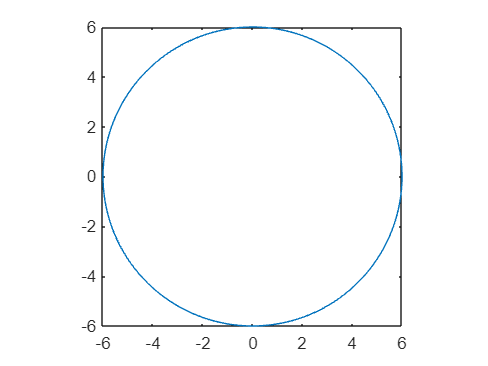

fplot(fx(theta1,0),fy(theta1,0))
axis equal

## Task 5

Now visualize the range of the smaller arm on the same axes by plotting `fx` and `fy` again, this time with `theta1` set to zero. Use `hold on` and `hold off` to add this plot to your current plot.

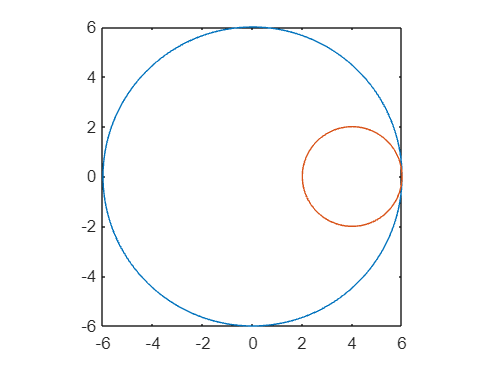

hold on
fplot(fx(0,theta2),fy(0,theta2))
axis equal
hold off

## Task 6

The `fsurf` function can visualize a surface using functions for the x, y, and z coordinates.

`fsurf``(``xFunction``,``yFunction``,``zFunction``)`

Task

Use `fsurf` to visualize everywhere the end effector can reach. Use `fx` and `fy` for the 

x and y coordinates. Use `0` for the z coordinate.

To better view the plot, you can use the command `view``(``2``)` to see the plot on the x-y plane and the command `axis` `equal` to make the axes equal.

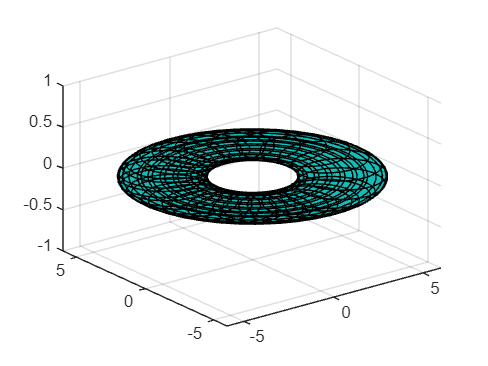

fsurf(fx,fy,0)

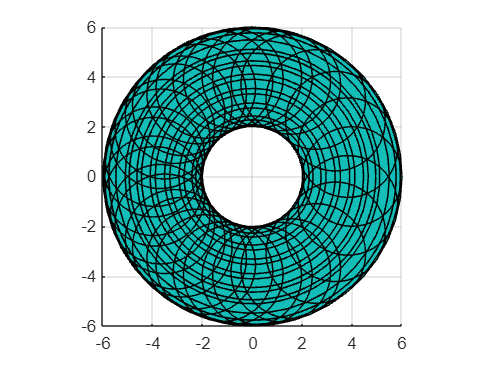

fsurf(fx,fy,0)
view(2)
axis equal